## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 02 - Central Difference and Bar Element**

**2.1 Potential, internal forces, and stiffness of a bar**

Let's get started with the bar element, which is a truss in 3D space. We can see it as a typical spring that we can buy from a hardware store. When you stretch or compress it, it will gives you a responsive force to return to its original length (see the following Figure). 

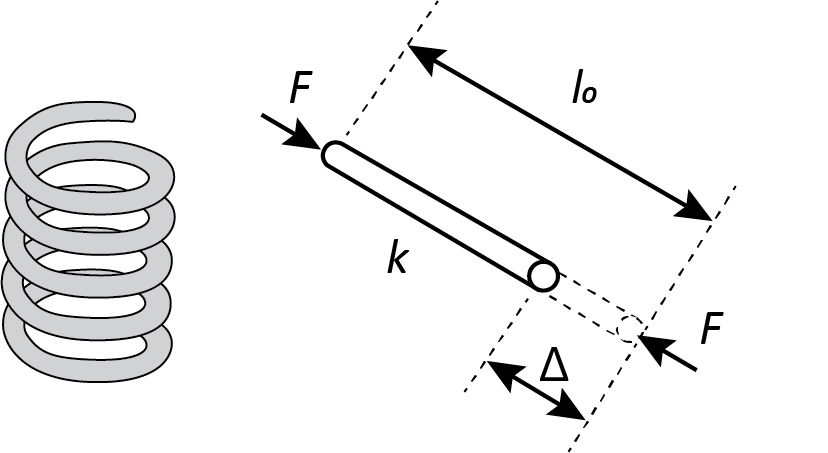

Let's assume that this bar element has linear elastic responses just like a spring that satify Hooke's Law. If we stretch our mind a little bit to remember the college physics 101, we know that reative force of a spring is porportional to its elongation or shortening:


$$F=k\Delta ,$$


where $k$ is the stiffness coefficient, and $\Delta \;$is the elongation or shortening. Moreover, we know that the strain energy stored within the spring can be obtained through integrating the force multiplying the deformation throughout the compression or elongation. Because the spring is linear elastic, the strain energy is quadratic:


$$U=\int_0^{\Delta \;} F\Delta^{\prime } \;d\Delta^{\prime } \;=\frac{1}{2}k\Delta {\;}^2$$


The stored strain energy is often referred to as potential - meaning the potential to do work. For a spring, this means pushing or pulling an object attached to it. The idea of a potential function is critical for computational mechanics - if we can find a potential of a hyper elastic deformable body, the first derivative of potential gives us the forces, while the second derivative gives us the stiffness. We can verify this using the above 1D spring: 


$$F=\frac{\partial U\;}{\;\partial \Delta \;}=\frac{\partial \left(\frac{1}{2\;}k\Delta {\;}^{2\;} \right)}{\;\partial \Delta \;}=2\;\frac{1}{2}k\Delta =k\Delta ,$$



$$K=\frac{\partial^{2\;} U\;}{\;\partial \Delta^{2\;} \;}=\frac{\partial F\;}{\;\partial \Delta \;}=k\ldotp$$


Nothing supprising so far right! Now, all the above derivation is for a 1D representation of the spring (bar/truss), how about moving everything to 3D? To represent a bar element, we just need two nodal cooridnates:


$$\begin{array}{l}
{\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}} =\left\lbrack x_i \;;\;\;y_i \;;{\;\;z}_{i\;} \right\rbrack ;\\
{\mathit{\mathbf{x}}}_{\mathit{\mathbf{j}}} =\left\lbrack x_j \;;\;\;y_j \;;{\;\;z}_{j\;} \right\rbrack \ldotp 
\end{array}$$
 

In this situation, we will need to use the nodal coordinate vector to represent the current length of the spring (bar/truss). By subtracting the original length of the spring from its current length, we obtain the elongation (or shortening). 

$\Delta =\sqrt{{\left({\mathit{\mathbf{x}}}_i -{\mathit{\mathbf{x}}}_j \right)}^2 }-l_0$.

Subsituting this above equation into the bar potential, we get:

$U_{\textrm{bar}} =\frac{1}{2}k_{\textrm{bar}} \left(\sqrt{{\left({\mathit{\mathbf{x}}}_i -{\mathit{\mathbf{x}}}_j \right)}^2 }-l_0 \right)$, or

$U_{\textrm{bar}} =\frac{1}{2}k_{\textrm{bar}} \left(\sqrt{{\left(x_i -x_j \right)}^2 +{\left(y_i -y_j \right)}^2 +{\left(z_i -z_j \right)}^2 }-l_0 \right)$.

In coding, we can implement this potential function as:

function PE=Bar_Potential(xi,xj,l0,kbar)
    % xi and xj are 3*1 vector
    % L0 is the original length
    % kbar is the stiffness of bar
    PE=0.5*kbar*((norm(xi-xj)-l0)/l0)^2;
end

**2.2 Central Difference**

Now that we have the potential calculated and coded. How can we obtain the internal force vector and the stiffness matrix? Remember how we get the internal force and stiffness for the 1D spring - we can take derivatives. For the 3D bar element, we will need to do it using multi-variable calculas because potential is a function of two three-by-one vectors ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{i}}\;} \;$and ${\mathit{\mathbf{x}}}_{\mathit{\mathbf{j}}}$. More specifically, the Jacobian vector will give us the internal force vector while the Hessian matrix will give us the stiffness matrix. 

The internal forces of the bar can be calculated as the Jacobian of the potential:


$${\mathit{\mathbf{F}}}_{\textrm{bar}} =\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}}$$



$${\mathit{\mathbf{F}}}_{\textrm{bar}} =\left\lbrack \begin{array}{c}
F_{x_{i\;} } \\
F_{y_{i\;} } \\
F_{z_{i\;} } \\
F_{x_{j\;} } \\
F_{y_{j\;} } \\
F_{z_{j\;} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{\partial U_{\textrm{bar}} }{\partial x_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial y_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial z_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial x_j }\\
\frac{\partial U_{\textrm{bar}} }{\partial y_j }\\
\frac{\partial U_{\textrm{bar}} }{\partial z_j }
\end{array}\right\rbrack$$


Calculating the Jacobian analyticall can be a time consuming process. Therefore, engineers can also use numerical methods to finish this calculation. Bascially, the derivative represents a slope of the function at a given point along a given variable axis. Therefore, we can approximate the slope using two adjacent values of the potential function and the spacing between the two values. This is shown in the following figure. 

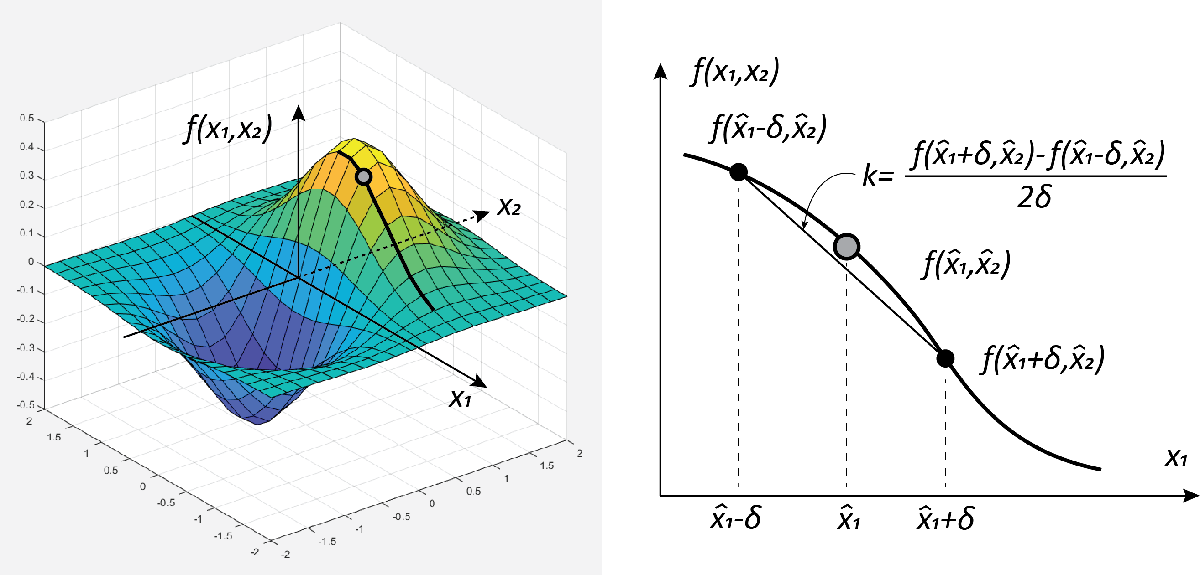

Next, we try to convert it to equations using the $x_{i\;} \;$and $y_i$ as two examples. The derivative about the two nodal coordiantes can be calculated using central difference as the following:


$$\frac{\partial U_{\textrm{bar}} }{\partial x_i }=\frac{U_{\textrm{bar}\;} \left(x_i +\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} \right)-U_{\textrm{bar}\;} \left(x_i -\delta \;,y_{i\;} ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} \right)}{2\delta \;}\;$$



$$\frac{\partial U_{\textrm{bar}} }{\partial y_i }=\frac{U_{\textrm{bar}\;} \left(x_i \;,y_{i\;} +\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} \right)-U_{\textrm{bar}\;} \left(x_i \;,y_{i\;} -\delta ,z_{i\;} ,x_j ,y_{j\;} ,z_{j\;} \right)}{2\delta \;}\;$$


We can repeat this for all six entries in the Jacobian vector and obtain the internal force vector. This calculation can also be done using a for loop as the following:

function F=Local_Bar_Force(xi,xj,l0,kbar,delta)
    F=zeros(6,1);
    % The local force vector is 6*1 vector
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        F(i)=(Bar_Potential(x_forward,xj,l0,kbar)-...
            Bar_Potential(x_backward,xj,l0,kbar))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        F(3+i)=(Bar_Potential(xi,x_forward,l0,kbar)-...
            Bar_Potential(xi,x_backward,l0,kbar))/2/delta;
        % calculate the central difference for the 
        % second node xj
    end
end

**2.3 Internal Force Vector Example**

Let's visualize the above code to understand what is going on. What we hope to do next is to visualize the direction of force computed using the central difference methods above. We create a bar, whose original nodal coordinates are:


$$X_i =\left\lbrack 0;0;0\right\rbrack ;\;\;X_j =\left\lbrack 1;0;0\right\rbrack \ldotp$$


In this situation, we know that the original length of the bar is 1. We will further set the stiffness of this bar to be 1 and use a central difference delta step with value ${10}^{-6} \ldotp$

% Assume the original nodal coordinates of the bar is 
% of the following values
Xi=[0;0;0];
Xj=[1;0;0];

l0=norm(Xj-Xi); % The original bar length
kbar=1; % The bar stiffness value
delta=10^-6; % Step length for the central difference method

Next, we set up the deformed bar location. Here, we assume that i-th node of this bar is still locaged at $\left\lbrack 0;0;0\right\rbrack$ location. You will be able to use the slider to define the other end of this bar.  

% The deformed nodal coordinates of the bar
xi=[0;0;0];
xj1=0.6;
xj2=0.4;
xj3=0.1;
xj=[xj1;xj2;xj3;];

Next, we use the function we created previously to calcualte the reaction force. This can be done with the following code. Basically, we just send in the requested variables. We can change the nodal coordinates using the above switches, and check how the values of the interal bar force change. 

% Solve for the forces of the bar
% Here we can directly use the function we already created
barForce=Local_Bar_Force(xi,xj,l0,kbar,delta);

Next, we want to plot the force on top of the deformed and undeformed bar configuration. This is accomplished using the following code:

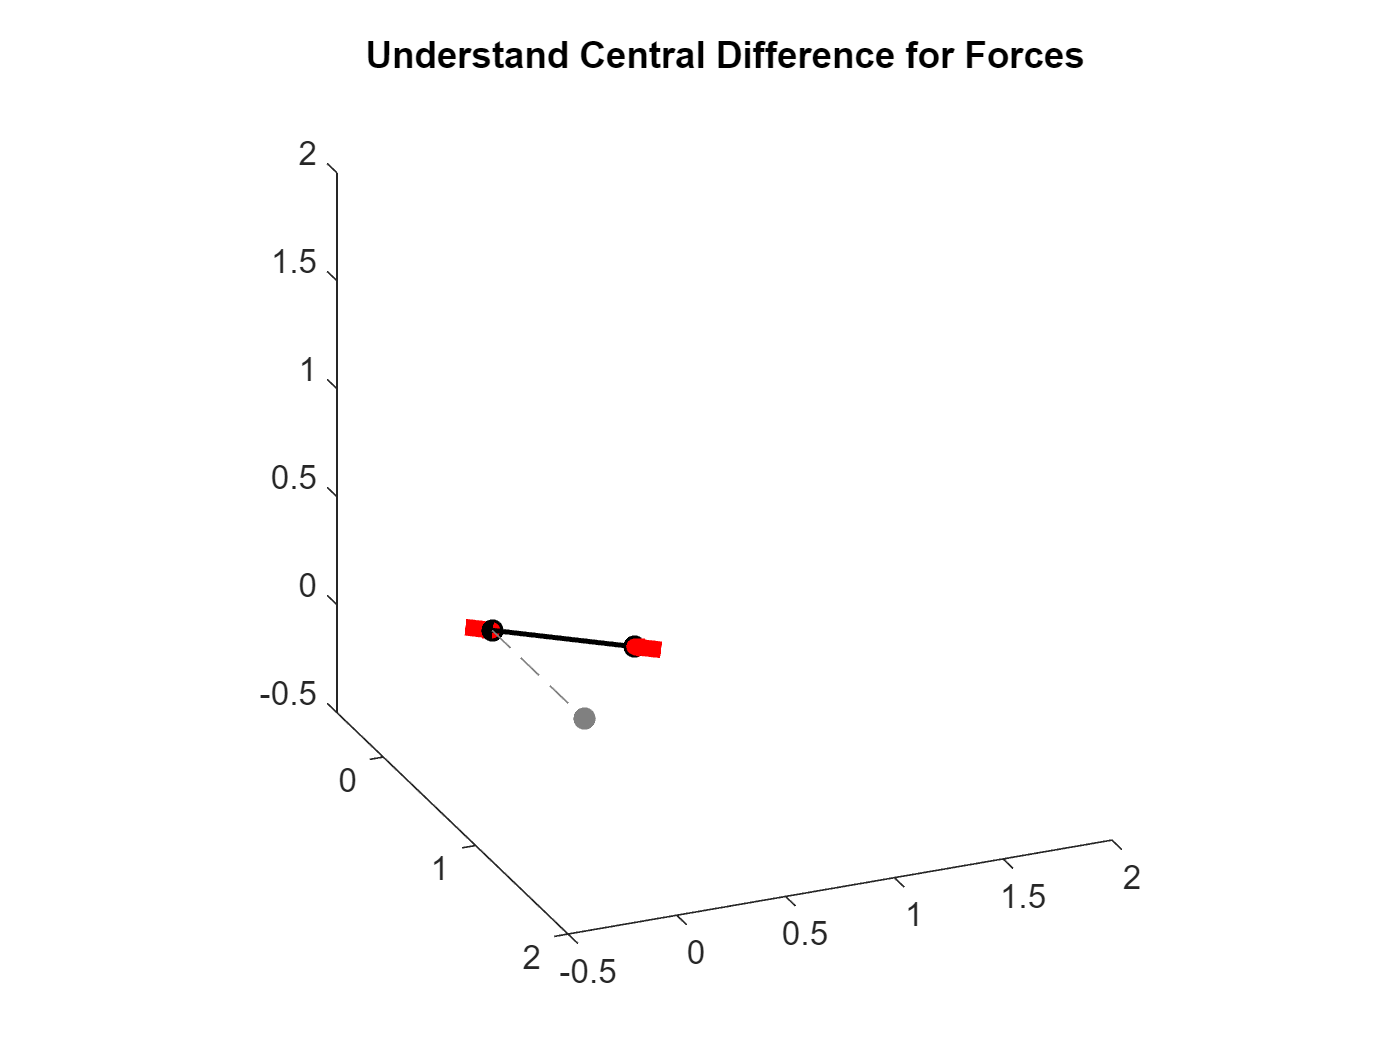

% Set the View Angle
view1=67;
view2=24;

% Plot the figgure
figure
hold on
title('Understand Central Difference for Forces')
view(view1,view2); 
set(gca,'DataAspectRatio',[1 1 1])
axis([-0.5,2,-0.5,2,-0.5,2])

% We first plot the deformed bar and the original bar
% This is the original bar location
plot3([Xi(1),Xj(1)],[Xi(2),Xj(2)],[Xi(3),Xj(3)],...
    Color=[0.5,0.5,0.5], LineStyle='--',...
    Marker='.', MarkerSize=20)
% This is the deformed bar location
plot3([xi(1),xj(1)],[xi(2),xj(2)],[xi(3),xj(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)

% Next we plot the forces acting on the bar
% We can use the Quiver function to do this
scaleFactor=0.5;
% This is the force at the i-th node
quiver3(xi(1)-barForce(1)*scaleFactor,...
    xi(2)-barForce(2)*scaleFactor,...
    xi(3)-barForce(3)*scaleFactor,...
    +barForce(1)*scaleFactor,...
    +barForce(2)*scaleFactor,...
    +barForce(3)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=5)
% This is the force at the j-th node
quiver3(xj(1)-barForce(4)*scaleFactor,...
    xj(2)-barForce(5)*scaleFactor,...
    xj(3)-barForce(6)*scaleFactor,...
    +barForce(4)*scaleFactor,...
    +barForce(5)*scaleFactor,...
    +barForce(6)*scaleFactor,...
    'r',AutoScale='off',MaxHeadSize=10,...
    LineWidth=5)

Now, play with the code and look at the forces from different directions. What you will notice is that red arrow marked forces are always along the deformed bar direction, which is exactly what should happen in reality. These extensional and compressive spring gives a reaction force in their axial directions. Moreover, you can see that as we stretch or compress the bar more, it will give a larger tensile or compressive forces. This also matches with the Hooke's Law we learned in College Physics 101. 

One interesting thing to note here. We can see that the modeling procedure automatically accomondate nonlinear and large deformation. We had not done anything fancy, but the nonlinear reaction forces is automatically captured through the central-difference pipeline. This is not something you can automatically obtain through the procedure outlined in FEM classes. 

**2.4 Hessian Matrix and Stiffness**

The stiffness matrix is the Hessian matrix of the total potential. If we work out all the equations, it will look like some thing as the following:


$${\mathit{\mathbf{K}}}_{\textrm{bar}} =\Delta_{\mathit{\mathbf{x}}} U_{\textrm{bar}} =\left\lbrack \begin{array}{cccccc}
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_i^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial y_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial z_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial x_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial y_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial x_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_i^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial z_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial x_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial y_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_i^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial x_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial y_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial z_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_j^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial y_j } & \frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial x_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial y_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial z_{i\;\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_j^{2\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial z_{j\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial x_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial y_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial z_{i\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial x_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial y_{j\;} } & \frac{\partial^2 U_{\textrm{bar}} }{\partial z_j^{2\;} }
\end{array}\right\rbrack$$


Hmmm..... 

This looks intimidating but is actually going to be simpler than what you thought. Let's take a look at the first column of the matrix. We have:


$$\left\lbrack \begin{array}{c}
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_i^{2\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{i\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{i\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial x_{j\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial y_{j\;} \partial x_{i\;} }\\
\frac{\partial^2 U_{\textrm{bar}} }{\partial z_{j\;} \partial x_{i\;} }
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left\lbrack \begin{array}{c}
\frac{\partial U_{\textrm{bar}} }{\partial x_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial y_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial z_i }\\
\frac{\partial U_{\textrm{bar}} }{\partial x_j }\\
\frac{\partial U_{\textrm{bar}} }{\partial y_j }\\
\frac{\partial U_{\textrm{bar}} }{\partial z_j }
\end{array}\right\rbrack =\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right)$$


Basically, this is to apply central difference about the $x_{i\;}$direction again to the force vector we previously computed. Then, applying the above notation to the full matrix will give us:


$${\mathit{\mathbf{K}}}_{\textrm{bar}} =\Delta_{\mathit{\mathbf{x}}} U_{\textrm{bar}} =\left\lbrack \begin{array}{cccccc}
\frac{\;\partial }{\;\partial \;x_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;y_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;z_{i\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;x_{j\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;y_j }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right) & \frac{\;\partial }{\;\partial \;z_{j\;} }\left(\nabla_{\mathit{\mathbf{x}}} U_{\textrm{bar}} \right)
\end{array}\right\rbrack$$


This representation gives us another way to look at the stiffness and it is very useful - we can code this out easily! Basically, we are applying another central difference step to the internal force function we created previously for each column. This can be implemented with the following code:

function K=Local_Bar_Stiff(xi,xj,l0,kbar,delta)
    K=zeros(6,6);
    % The local stiffness matrix is 6*6 matrix
    for i=1:3
        x_forward=xi;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xi;
        x_backward(i)=x_backward(i)-delta;
        K(i,:)=(Local_Bar_Force(x_forward,xj,l0,kbar,delta)-...
            Local_Bar_Force(x_backward,xj,l0,kbar,delta))/2/delta;
        % calculate the central difference for the 
        % first node xi

        x_forward=xj;
        x_forward(i)=x_forward(i)+delta;
        x_backward=xj;
        x_backward(i)=x_backward(i)-delta;
        K(3+i,:)=(Local_Bar_Force(xi,x_forward,l0,kbar,delta)-...
            Local_Bar_Force(xi,x_backward,l0,kbar,delta))/2/delta;
        % calculate the central difference for the 
        % second node xj
    end
end

Yes! The code looks exactly the same - we only change the potential function to the local force function and we are done! This is the beauty of mathematics and mechanics. 

Let's verify the result using the following demonstration. Here, we want to put the bar element along the x-axis and extend or compress it. We want to see what stiffness we can get out of this system as we change its length. 

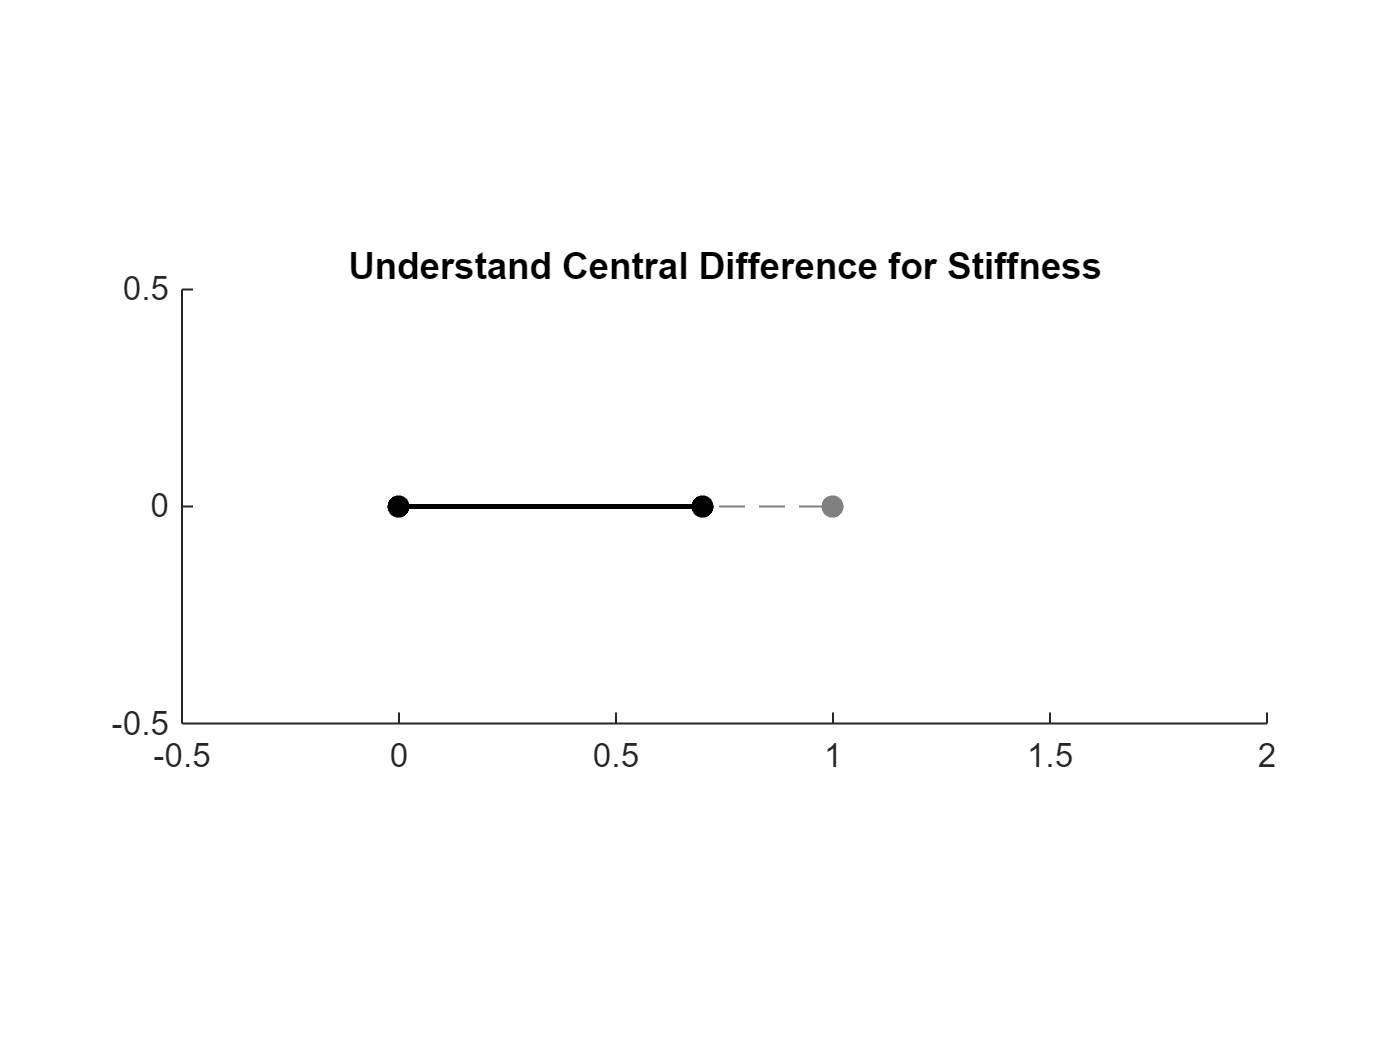

xi_stiff1=[0;0;0];
xj1=0.7;
xj_stiff1=[xj1;0;0;];

% Set the View Angle
view1=0;
view2=0;

% Plot the figgure
figure
hold on
title('Understand Central Difference for Stiffness')
view(view1,view2); 
set(gca,'DataAspectRatio',[1 1 1])
axis([-0.5,2,-0.5,2,-0.5,0.5])

% We first plot the deformed bar and the original bar
% This is the original bar location
plot3([Xi(1),Xj(1)],[Xi(2),Xj(2)],[Xi(3),Xj(3)],...
    Color=[0.5,0.5,0.5], LineStyle='--',...
    Marker='.', MarkerSize=20)
% This is the deformed bar location
plot3([xi_stiff1(1),xj_stiff1(1)],[xi_stiff1(2),xj_stiff1(2)],[xi_stiff1(3),xj_stiff1(3)],...
    Color='black',Marker='.',...
    MarkerSize=20, LineWidth=1.5)

The above code will showthe deformed bar plotted on top of the bar with the oritingal length.

We can next find the stiffness of the bar assocated with the plotted deformation. 

% Solve for the stiffness of the bar
barK=Local_Bar_Stiff(xi_stiff1,xj_stiff1,l0,kbar,delta);
barK=barK(4,4)

barK = 1.0000

In this condition, the stiffness value from the matrix in the [4,4] index is associated with the xj1 direction. We can see that the stiffness is a constant 1 regardless of how we stretch or compress the bar. This is expected because the stiffness of bar is indeed set as 1. 

Next, we try to push the j-node to move in circle from its at rest location and maintain a unit length. This is illustrated in the following figure. The angle $\theta \;$controls the configuration of the bar and we hope to recorde the stiffness in the x1 direction at the node j. This stiffness is corresponding to the force value we obtain when the node is deformed towards the x1 direction with a infinitesimal unit deformation. We can also find how this stiffness changes as we rotate the bar using the following code. 

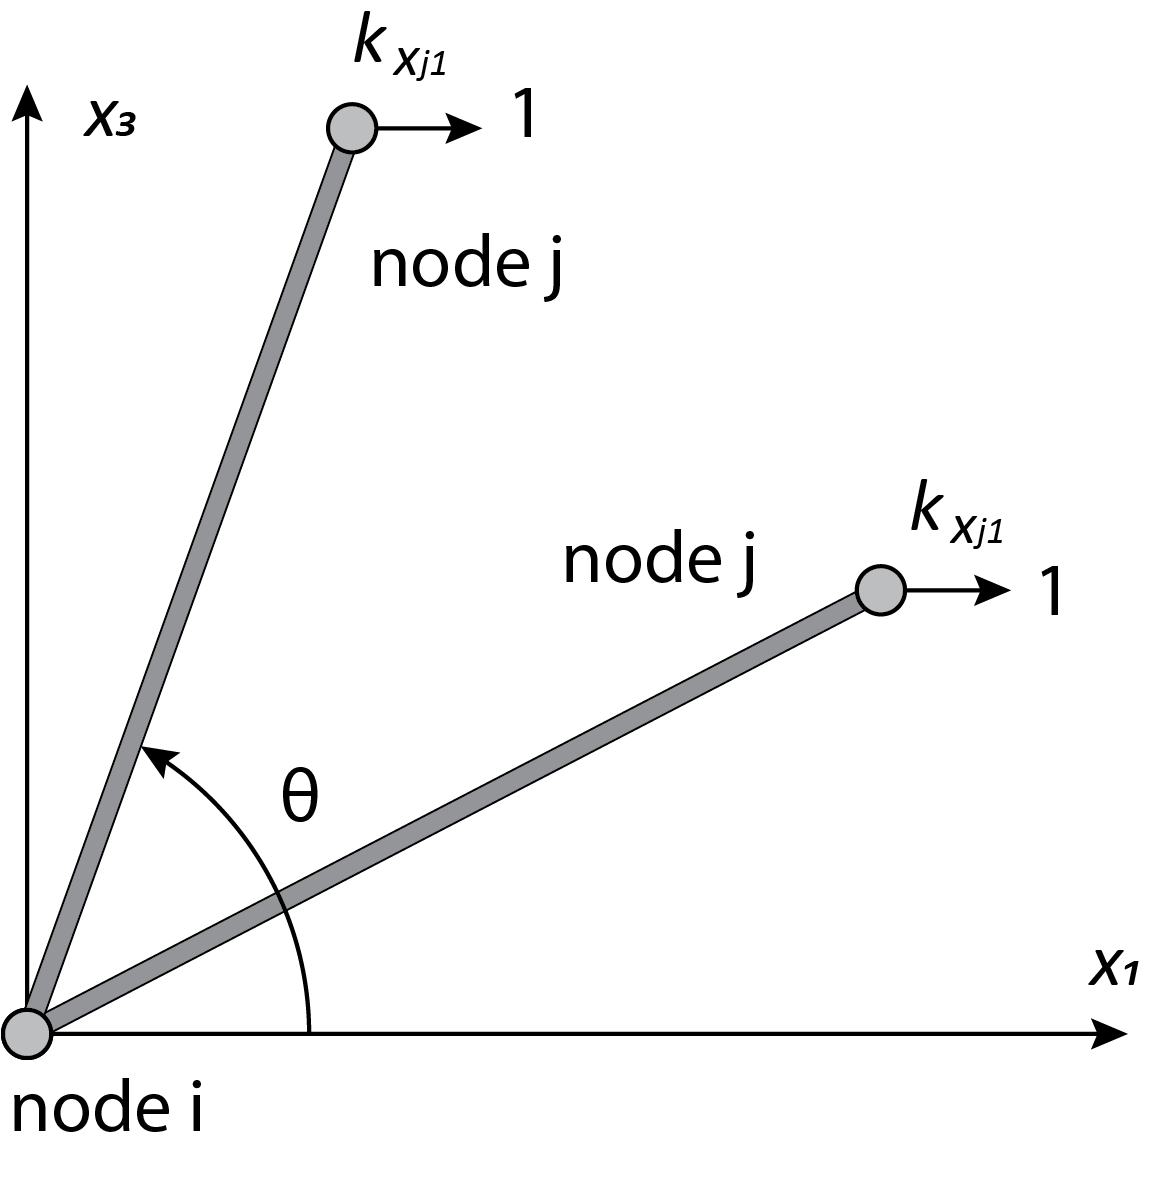

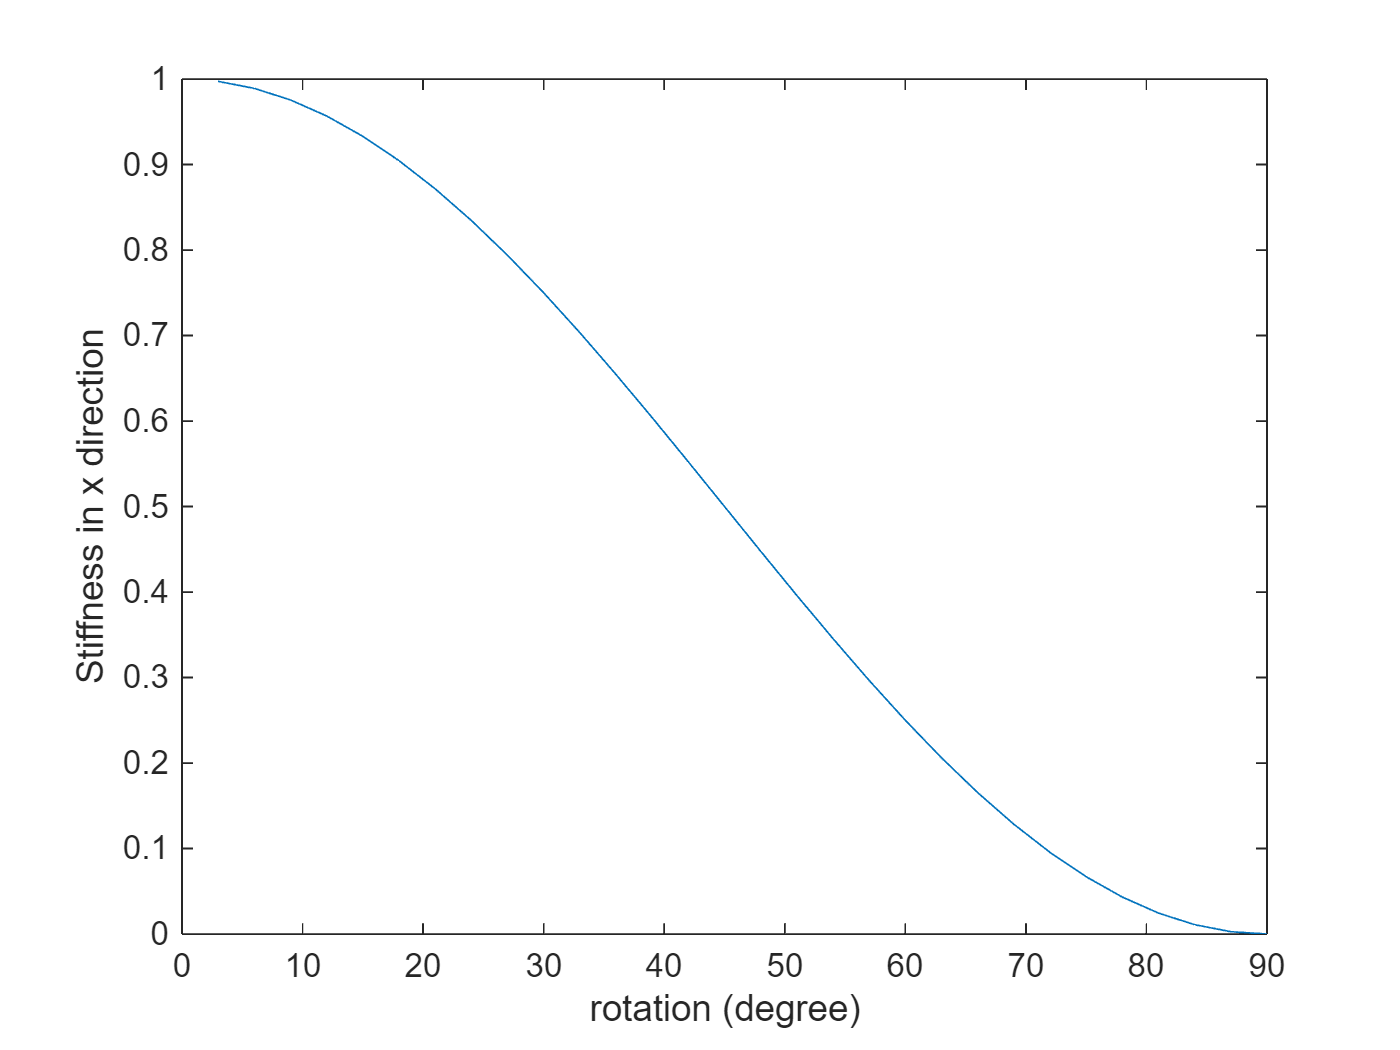

stiffHis=zeros(30,1);
theta=zeros(30,1);
% This is used to store result
for k=1:30
    theta(k)=3*k; % angle in degree
    xi=[0;0;0];
    xj=[cosd(theta(k));0;sind(theta(k));];
    % We gradually put the j-node move up in z-direction
    barK=Local_Bar_Stiff(xi,xj,l0,kbar,delta);
    stiffHis(k)=barK(4,4);
end

figure
plot(theta,stiffHis)
xlabel('rotation (degree)')
ylabel('Stiffness in x direction')

The result is shown above, and we see that the stiffness gradually drops to zero when the rotation reaches 90 degree. This is exactly what we should expect. When the bar is rotated to 90 degree angle, it is pointing upward and it should not produce stiffness in the x-axis direction. These verification help us to verify that the developed function is accurate and correct. 

**2.5 Object oriented programming**

Finally, we want to discuss a programming concept called object oriented programming. This is a necessary tool we need to use to organize the software program to avoid repeating code and also to create better architecture for the code. The following figure introduces the concept of object oriented programming. There are two key concepts: Class and Object. 

Class is a virtualized object. It is not living in the RAM of our computer and thus cannot use CPU or GPU resources to do anything. We can think of it as the Peashooter Card in PVZ games. You know, it is a card that is not yet built on the grass boxes so it cannot shoot zombies. 

On the contrary, Object is a physicalized class. It is built based on the class. It is created to occupy RAM of our computer and thus it can use CPU and GPU resource to really compute results for us. With the PVZ example, object is like a Peashooter we actually plant on the grass box after paying the sunlight. This Peashooter object can now shoot the zombies! 

Multiple objects can be created from the same class. For instance we can create the ps1 Peashooter and the ps2 Peashooter based on the same Peashooter class. These objects can store variables to represent their own characteristics. For example, the ps1 Peashooter is at [1,1] location while the ps2 Peashooter is at [2,1] location. Finally, the objects can perform certain actions through using predefined functions. For example, we can ask the ps1 Peashooter to shoot down a zombie like "ps1.Shoot();"

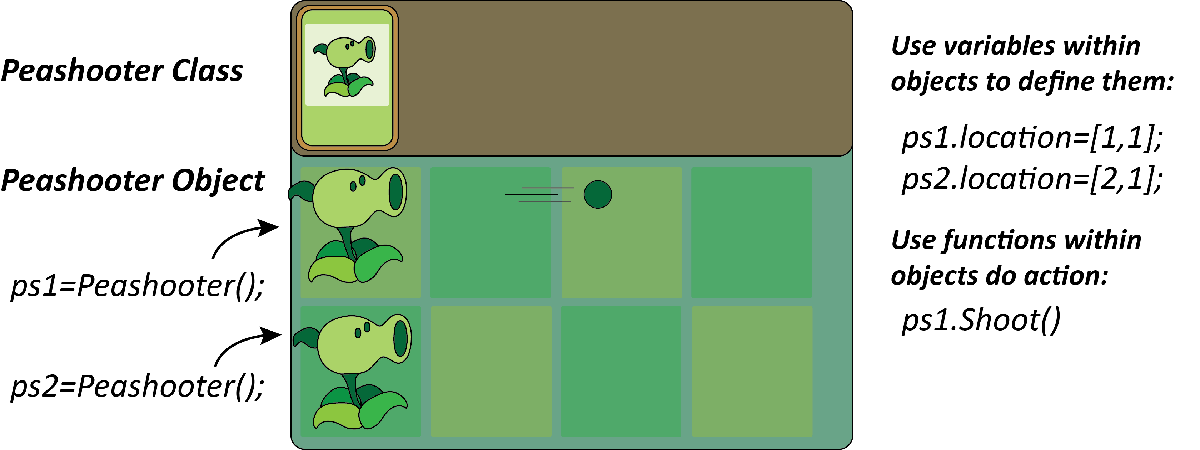

Here, in the Sim-FAST package (and also in any other FEM-like package), the element class will store all the functions we have created previously. For example, the "CD_Elements_Bars" stores the internal force and stiffness calculation function we previously defined. Let's see how we can use them. We will create a bar element object from the class using the following code:

% Create the bar (truss) element
bar=CD_Elements_Bars();

**Please add the source code folder to path before running the above line!!**

Let's define another truss element to compare what we derived previously with this stock bar element. Assume that we have two nodes and they are "x_comp_i" and "x_comp_j". We can also assume that the original length of the bar is $L_{0\;} =1$; the Young's modulus is $E=1$; the cross section area $A=1;$ stiffness is $k=\frac{\textrm{EA}}{L_{0\;} }=1$, and the central difference step is $\delta ={10}^{-6\;} \ldotp$

% Nodal coordinates
x_comp_i=[0;0;0];
x_comp_j1=0;
x_comp_j2=0;
x_comp_j3=1;
x_comp_j=[x_comp_j1;x_comp_j2;x_comp_j3;];
% Other parameters:
L0=1;
E=1;
A=1;
k=E*A/L0;
delta=10^-6;

% Forces from the stock element
bar.delta=delta;
F_bar_stock_element=bar.Solve_Local_Force(x_comp_i,x_comp_j,L0,E,A)

F_bar_stock_element = 1.0e-16 *

         0
         0
    0.5551
         0
         0
   -0.5551


% Forces from the function derived in this file
F_bar_this_file=Local_Bar_Force(x_comp_i,x_comp_j,L0,k,delta)

F_bar_this_file = 1.0e-16 *

         0
         0
    0.5551
         0
         0
   -0.5551


WOW! They look identical (Of course right  : |  Why am I pretended to be exciting)

Similarly, we can compare the stiffness matrix. Please feel free to change the nodal coordinate to compare other situations and verify that the functions derived in this live script file indeed matches that from the stock bar element. 

% Stiffness from the stock function
K_bar_stock_element=bar.Solve_Local_Stiff(x_comp_i,x_comp_j,L0,E,A)

K_bar_stock_element =     0.0000         0         0   -0.0000         0         0
         0    0.0000         0         0   -0.0000         0
         0         0    1.0000         0         0   -1.0000
   -0.0000         0         0    0.0000         0         0
         0   -0.0000         0         0    0.0000         0
         0         0   -1.0000         0         0    1.0000


% Stiffness from the function created in this file
K_bar_this_file=Local_Bar_Stiff(x_comp_i,x_comp_j,L0,k,delta)

K_bar_this_file =     0.0000         0         0   -0.0000         0         0
         0    0.0000         0         0   -0.0000         0
         0         0    1.0000         0         0   -1.0000
   -0.0000         0         0    0.0000         0         0
         0   -0.0000         0         0    0.0000         0
         0         0   -1.0000         0         0    1.0000


Fantastic! They also match each other!

Now, why do we create the class? Because it help us to better organize the code as we start adding in mutliple truss elements or even when we add other elements. The class will help us avoid copy pasting codes and help us to navigate the code. Check out the source code of this package. Without using object oriented programming, we will have hundreds of functions stored in one folder! That is not ideal. 

Anyway, this is what I hope to include here. Please also check out the following links if you want to learn more about object oriented programming. 

See also the introduction of OOP in Wiki:

[https://en.wikipedia.org/wiki/Object-oriented_programming](https://en.wikipedia.org/wiki/Object-oriented_programming)

Also see the documentation for MATLAB OOP:

[https://www.mathworks.com/help/matlab/matlab_oop/why-use-object-oriented-design.html](https://www.mathworks.com/help/matlab/matlab_oop/why-use-object-oriented-design.html)

If you read Chinese check this out:

[https://www.amazon.com/%E5%A4%A7%E8%AF%9D%E8%AE%BE%E8%AE%A1%E6%A8%A1%E5%BC%8F-%E7%A8%8B%E6%9D%B0/dp/B0011FHN5S](https://www.amazon.com/%E5%A4%A7%E8%AF%9D%E8%AE%BE%E8%AE%A1%E6%A8%A1%E5%BC%8F-%E7%A8%8B%E6%9D%B0/dp/B0011FHN5S)

程杰《大话设计模式》我小学初中入门编程时候看的书，非常推荐。